## **Question 2**

**This notebook (along with associated helper functions) completes the following tasks as outlined by question 2.**

- Choose an assimilation window [t0, tN] with N ≥ 2. (Chose N=2)

- Generate reference solution x ref 0:N by solving the Lorenz’63 system using Matlab’s ode45 function starting from (4).

- Generate synthetic observations from the reference solution by adding realizations of the observation error, yi = x ref i + ε obs i . Here the observation operator is the identity operator, and observation errors have a Gaussian distribution N (0, R). Choose your R.

- Choose an initial background state by a random draw from the normal distribution (4)

- Run the model (6) starting from x b 0 to obtain the background trajectory x b 0:N.

- Select your numerical unconstrained optimization solver (fminunc)

- Run the 4D-Var algorithm 3.3. Compare your background trajectory x b 0:N, analysis trajectory x a 0:N, and reference trajectory x ref 0:N by plotting them on the same graph. We want to see that the analysis is a better match to the reference than the background.

clear;
close all;
clc;

% Setting seed for reproducibility
rng(3819963)

% Importing Lorenz96 model
m = otp.lorenz63.presets.Canonical;

% Model configurations
n_states = 3;
n_obs_states = 2;

% Inital conditions
x0 = [-10.0375; -4.3845; 34.6514];
B0 = [12.4294, 12.4323, -0.2139; 12.4323, 16.0837, -0.0499; -0.2139, -0.0499, 14.7634];
x0_ref = x0;

% Time steps
dt = 0.1; % time step unit
h = dt/200;
T_max = 0.2; % size of assimilation window

% Draw X0 from dist
x0_b = mvnrnd(x0,B0)';

% Reference trajectory (At timestamps of observations)
x = x0;
T = 0:dt:T_max;
X_ref = zeros(3,length(T));
X_ref(:, 1) = x;
for i = 1:(length(T)-1)
    [~, x] = ode45(m.RHS.F, [T(i), T(i+1)], x);
    x = x(end, :);
    X_ref(:, i+1) = x;
end

% Observations
% Generating observation operator (observing first two states)
H = [1, 0, 0;
    0, 1, 0;
    0, 0, 0];

% Applying observation vector to reference trajectory
X_obvs = H * X_ref;
X_obvs_ens = repmat(X_obvs, 1,1, 1);
obvs_sigma = 0.025;
obvs_noise = normrnd(0,obvs_sigma,size(X_obvs_ens));  % (note normrnd(mu,sigma))
obvs_noise(3,:,:) = 0;
X_obvs_ens = X_obvs_ens + obvs_noise;

% 4D-Var optimization
f = @(x)var4(x,x0_b,X_obvs_ens,T_max,dt);
options = optimoptions('fminunc','Display','iter','Algorithm','trust-region','SpecifyObjectiveGradient',true);
x = x0_b;

% Running 5 iterations of the optimization, with updated background
% states
for k = 1:5
    xb = x;
    f = @(x)var4(x,xb,X_obvs_ens,T_max,dt);
    [x0_a,fval,exitflag,output] = fminunc(f,x,options);
    x = x0_a
end


                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0             368.67                          71.4                
     1            89.1185        5.85355           72.8           1
     2            25.9995        2.35844           30.3           1
     3             10.517        1.92557           11.6           1
     4            3.14286       0.972256           11.7           1
     5             2.2902       0.901041           4.89           1
     6            1.98203       0.210733           1.82           1
     7            1.72976       0.627646           4.56           1
     8            1.50457       0.118865           1.15           1
     9            1.33689       0.110053           0.61           1
    10            1.32141      0.0439758          0.416           1
    11            1.28582      0.0740785          0.832           1
    12            1.27667       0.020606        

x =   -10.0872
   -4.3681
   34.6536



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0          0.0297969                         0.393                
     1          0.0208593      0.0269192          0.249           1
     2           0.020241     0.00533555         0.0183           1
     3          0.0200148     0.00540106         0.0332           1
     4          0.0199994    0.000935745        0.00551           1
     5          0.0199994     0.00065344        0.00551           1
     6          0.0199994     0.00016336        0.00551           0
     7          0.0199994      4.084e-05        0.00551           0
     8          0.0199994      1.021e-05        0.00551           0
     9          0.0199994     2.5525e-06        0.00551           0
    10          0.0199994    6.38125e-07        0.00551           0

Local minimum possible.

fminunc sto

x =   -10.0603
   -4.3642
   34.6430



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0          0.0198951                       0.00644                
     1          0.0198883    0.000789672        0.00476           1
     2          0.0198883    0.000432652        0.00476           1
     3          0.0198883    0.000108163        0.00476           0
     4          0.0198883    2.70407e-05        0.00476           0
     5          0.0198883    6.76018e-06        0.00476           0
     6          0.0198883    1.69005e-06        0.00476           0
     7          0.0198883    4.22511e-07        0.00476           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x =   -10.0599
   -4.3646
   34.6435



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0          0.0198881                        0.0048                
     1          0.0198881    0.000427727         0.0048           1
     2          0.0198881    0.000106932         0.0048           0
     3          0.0198881    2.67329e-05         0.0048           0
     4          0.0198881    6.68323e-06         0.0048           0
     5          0.0198881    1.67081e-06         0.0048           0
     6          0.0198881    4.17702e-07         0.0048           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<

x =   -10.0599
   -4.3646
   34.6435



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0          0.0198881                        0.0048                
     1          0.0198881    0.000427727         0.0048           1
     2          0.0198881    0.000106932         0.0048           0
     3          0.0198881    2.67329e-05         0.0048           0
     4          0.0198881    6.68323e-06         0.0048           0
     5          0.0198881    1.67081e-06         0.0048           0
     6          0.0198881    4.17702e-07         0.0048           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<

x =   -10.0599
   -4.3646
   34.6435


% Run high res forward models using inital conditions

T_high_res = 0:dt/100:T_max;
x_a = zeros(3,length(T_high_res));
x = x0_a;
x_a(:, 1) = x;
for i = 1:(length(T_high_res)-1)
    [~, x] = ode45(m.RHS.F, [T_high_res(i), T_high_res(i+1)], x);
    x = x(end, :);
    x_a(:, i+1) = x;
end

x_b = zeros(3,length(T_high_res));
x = x0_b;
x_b(:, 1) = x;
for i = 1:(length(T_high_res)-1)
    [~, x] = ode45(m.RHS.F, [T_high_res(i), T_high_res(i+1)], x);
    x = x(end, :);
    x_b(:, i+1) = x;
end

x_ref = zeros(3,length(T_high_res));
x = x0_ref;
x_ref(:, 1) = x;
for i = 1:(length(T_high_res)-1)
    [~, x] = ode45(m.RHS.F, [T_high_res(i), T_high_res(i+1)], x);
    x = x(end, :);
    x_ref(:, i+1) = x;
end


x0_a; 

**Generating plots of high res trajectories**

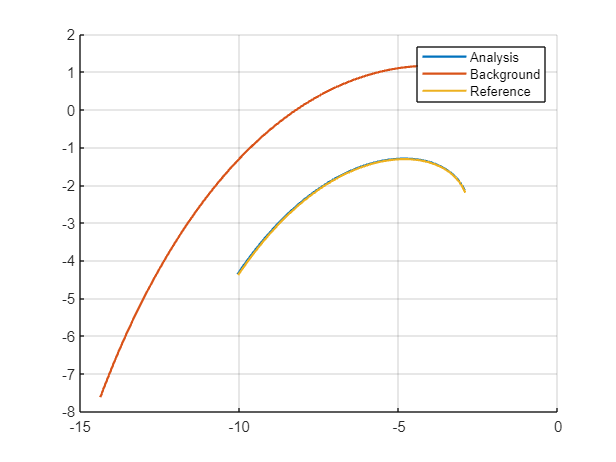

clf
hold on
plot3(x_a(1, :), x_a(2, :), x_a(3, :),'linewidth',1.5,'DisplayName', 'Analysis');
plot3(x_b(1, :), x_b(2, :), x_b(3, :),'linewidth',1.5,'DisplayName', 'Background');
plot3(x_ref(1, :), x_ref(2, :), x_ref(3, :),'linewidth',1.5,'DisplayName', 'Reference');
grid on
legend

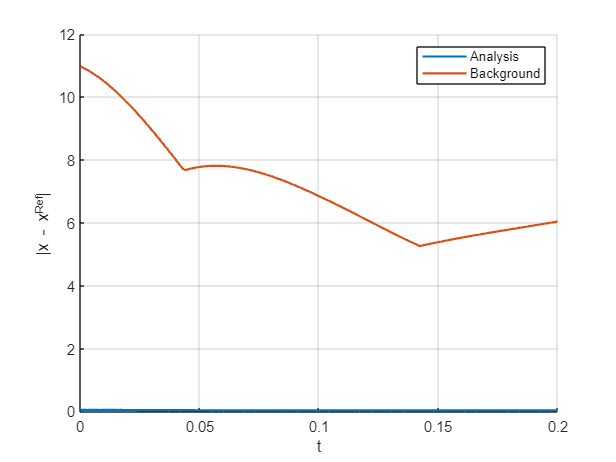

clf
hold on
plot(T_high_res,(sum(abs(x_a-x_ref),1)), 'linewidth',1.5, 'DisplayName', 'Analysis');
plot(T_high_res,(sum(abs(x_b-x_ref),1)), 'linewidth',1.5, 'DisplayName', 'Background');
xlabel('t') ;
ylabel('|x - x^{Ref}|');
xlim([T_high_res(1),T_high_res(end)]);
legend
grid on

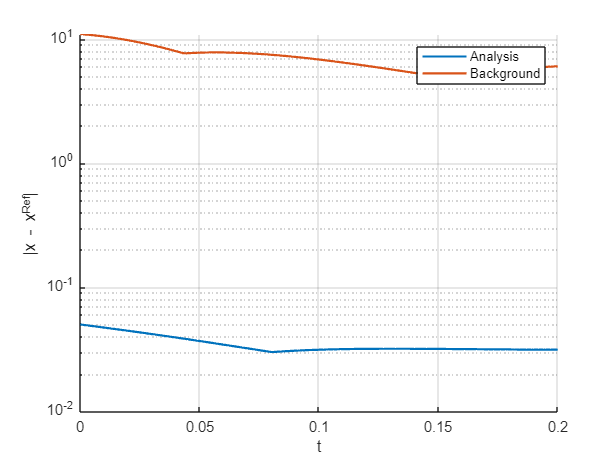

clf
hold on
plot(T_high_res,(sum(abs(x_a-x_ref),1)), 'linewidth',1.5, 'DisplayName', 'Analysis');
plot(T_high_res,(sum(abs(x_b-x_ref),1)), 'linewidth',1.5, 'DisplayName', 'Background');
xlabel('t') ;
ylabel('|x - x^{Ref}|');
xlim([T_high_res(1),T_high_res(end)]);
set(gca,'yscale','log')
legend
grid on